
% load train set (1.a)
readYaleFaces;

The matrix A is loaded in memory. Its size is:
       77760         150



size(A(:, 1))

ans =        77760           1


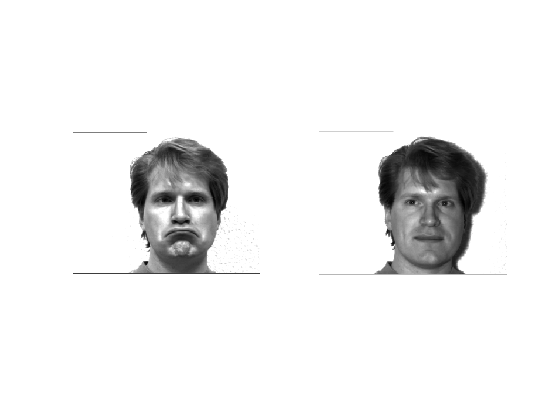

imshow(reshape(A(:,1), 243,320), [])

% A - is the training set matrix where each column is a face image
% train_face_id - an array with the id of the faces of the training set.
% image1--image20 are the test set.
% is_face - is an array with 1 for test images that contain a face
% faec_id - is an array with the id of the face in the test set, 
%           0 if no face and -1 if a face not from the train-set.


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Your Code Here  %
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

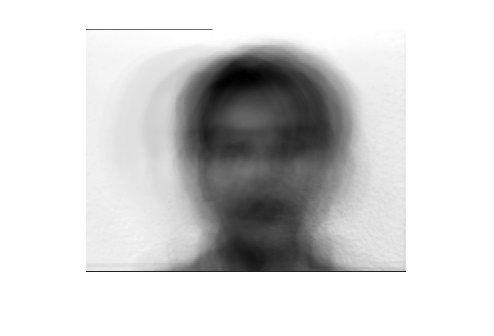

width = 320;
height = 243;

% Subtract mean image (1.b)
mean_face = mean(A, 2);
A_zero_mean = A - mean_face;

% Display mean image (1.c)
figure();
imshow(reshape(mean_face, height, width), []);

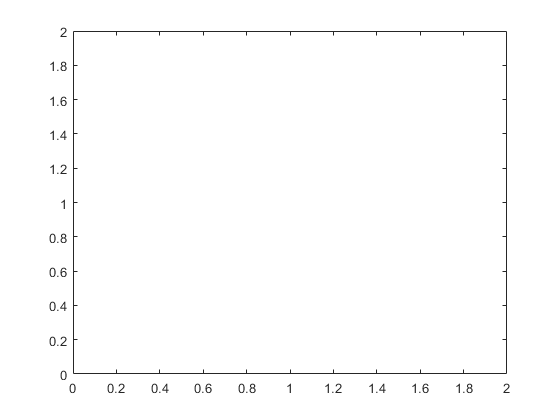


% Compute eigenvectors and report first 5 eigen-faces (2)
[eigen_vectors] = rLargestEigenVectors(A_zero_mean',5);

figure()
plot(a)

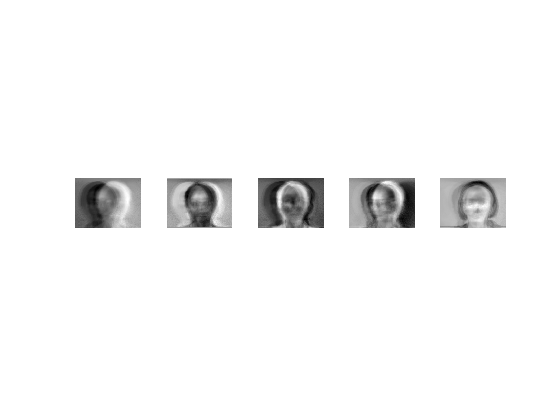


figure();
for i = 1:5
    subplot(1,5,i);
    imshow(reshape(eigen_vectors(:,i), height, width), []);
end


% Display and compute the representation error for the training images (3)
N = 150;
W = rLargestEigenVectors(A_zero_mean', 25);

A_representation = W' * A_zero_mean;
A_reconstruct = W * A_representation + mean_face;

A_reconstruct = A_reconstruct - min(A_reconstruct, [], 1);
A_reconstruct = A_reconstruct ./ max(A_reconstruct, [], 1) .* 255;

error = A_reconstruct - A;
error = error .^ 2;
error = sum(sum(error));
error = error / N;
error = sqrt(error)

error = 9.5944e+03

i = 1

error = 979.1460

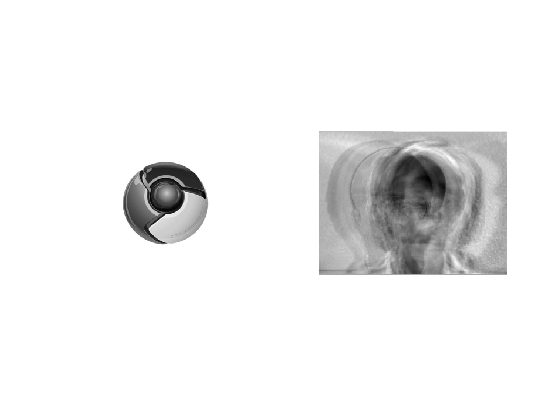


% Compute the representation error for the test images. Classify the test images and report error rate (4)
test_set = {image1, image2, image3, image4, image5, image6, image7, image8, image9, image10, image11, image12, image13, image14, image15, image16, image17, image18, image19, image20};

for i = 1:1
    img = test_set{1,i};
    img = reshape(img,[],1);
    img = cast(img, 'like', mean_face);
    y = W' * (img - mean_face);
    reconstruct = W * y + mean_face;
    
    error = (reconstruct - img) .^ 2;
    error = sum(sum(error)) / N;
    i
    error = sqrt(error)
    
    figure();
    subplot(1,2,1);
    imshow(reshape(img, height, width), []);
    subplot(1,2,2);
    imshow(reshape(reconstruct, height, width), []);
end

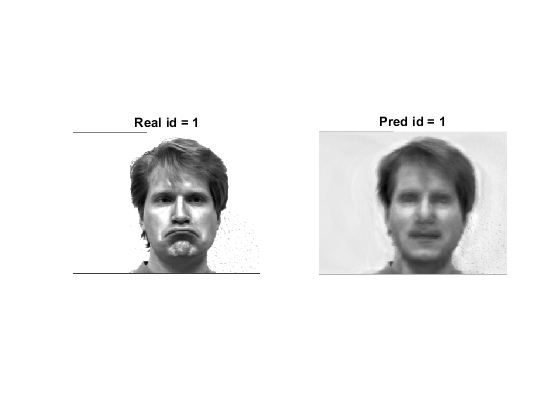

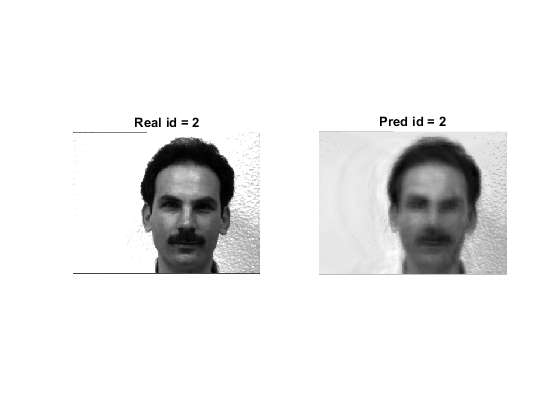

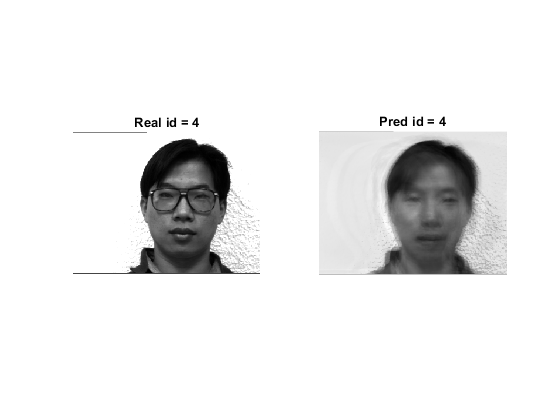

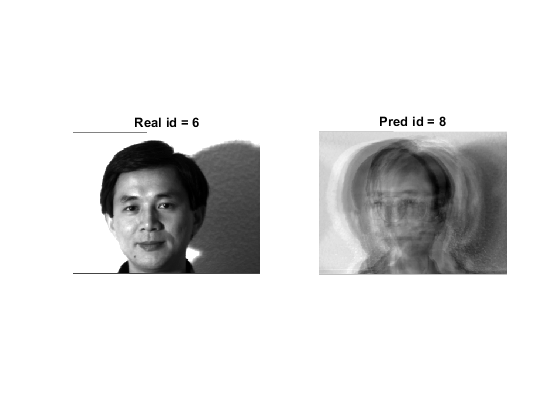

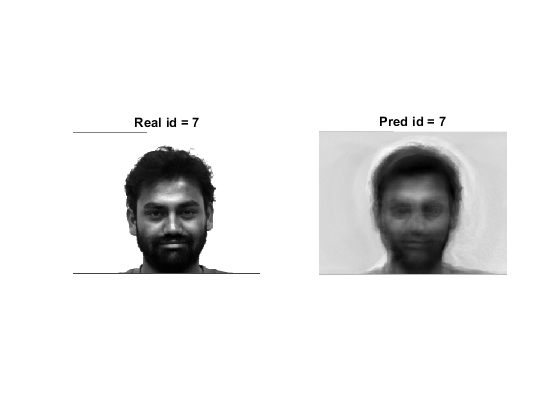

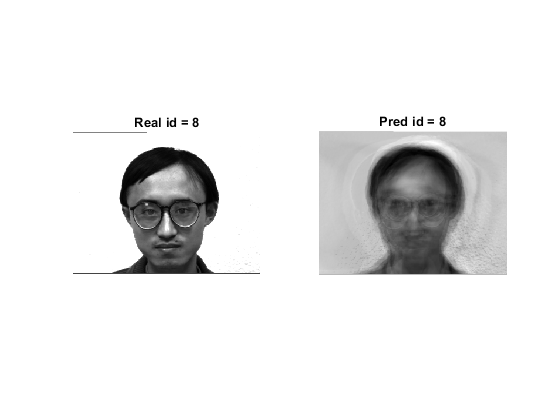

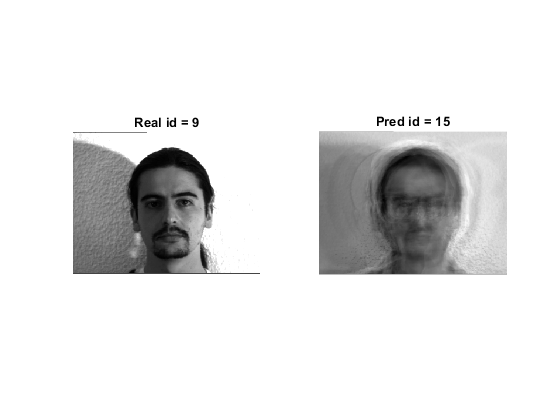

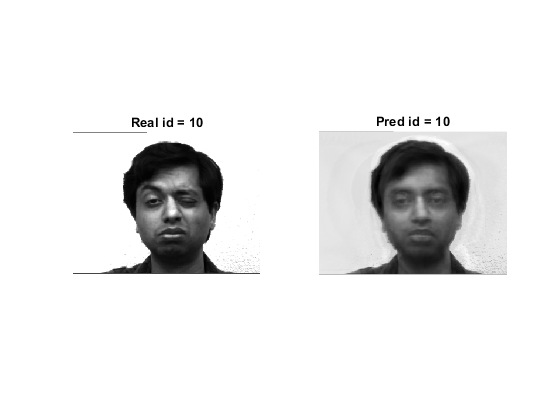


knn = fitcknn(A_representation', train_face_id');
num_correct = 0;
total = 0;
for i = 1:20
    if face_id(i) > 0
        total = total + 1;
        img = test_set{1,i};
        img = reshape(img,[],1);
        img = cast(img, 'like', mean_face);
        y = W' * (img - mean_face);
        reconstruct = W * y + mean_face;
    
        real_id = face_id(i);
        id_pred = predict(knn, y');

        figure();
        subplot(1,2,1);
        imshow(reshape(img, height, width), []);
        title(['Real id = ' , int2str(real_id)]);
        subplot(1,2,2);
        imshow(reshape(reconstruct, height, width), []);
        title(['Pred id = ' , int2str(id_pred)]);
        
        if real_id == id_pred
            num_correct = num_correct + 1;
        end
        
    end
end


total

total = 11

num_correct

num_correct = 9

success_ratio = num_correct / total

success_ratio = 0.8182